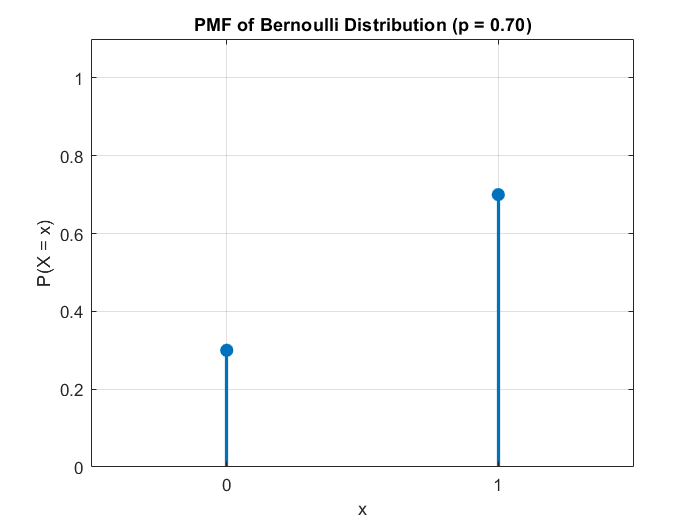

% Parameters
p = 0.7;  % Probability of success (at x = 1)

% Support of Bernoulli distribution
x = [0, 1];                  % Possible outcomes
pmf = [1 - p, p];            % Corresponding probabilities

% Plotting the PMF
stem(x, pmf, 'filled', 'LineWidth', 2);
xticks([0 1]);
xlim([-0.5, 1.5]);
ylim([0, 1.1]);
xlabel('x');
ylabel('P(X = x)');
title(sprintf('PMF of Bernoulli Distribution (p = %.2f)', p));
grid on;

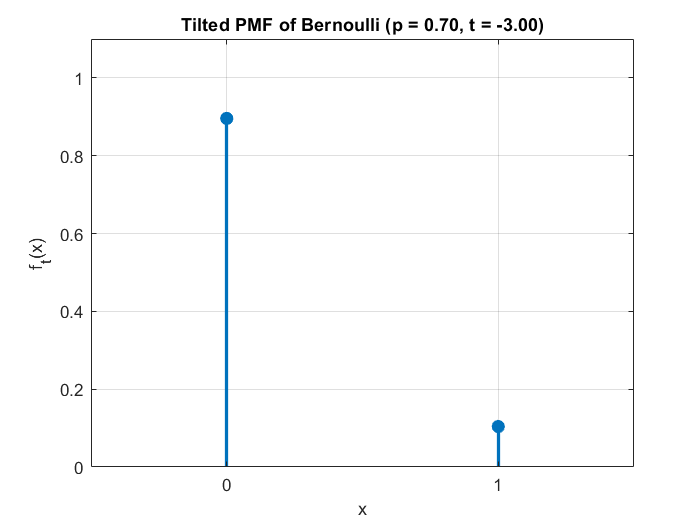

% Compute tilted probabilities
t = -3;         % Tilt parameter
Z = p * exp(t) + (1 - p);   % Normalizing constant
f1 = (p * exp(t)) / Z;      % Tilted probability at x = 1
f0 = (1 - p) / Z;           % Tilted probability at x = 0

% Support
x = [0, 1];
tilted_pmf = [f0, f1];

% Plot
stem(x, tilted_pmf, 'filled', 'LineWidth', 2);
xticks([0 1]);
xlim([-0.5, 1.5]);
ylim([0, 1.1]);
xlabel('x');
ylabel('f_t(x)');
title(sprintf('Tilted PMF of Bernoulli (p = %.2f, t = %.2f)', p, t));
grid on;

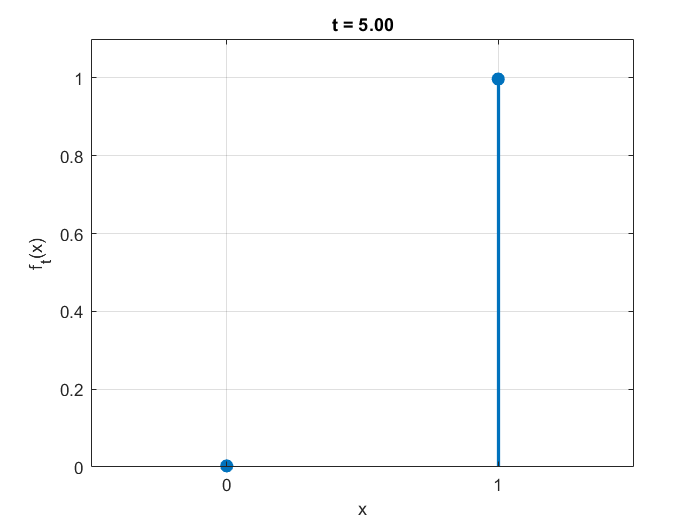

% Parameters
p = 0.7;
t_vals = -5:0.25:5;

output_folder = 'tilted_frames';
mkdir(output_folder);  % Create folder if it doesn't exist

for i = 1:length(t_vals)
    t = t_vals(i);
    
    % Tilted probabilities
    Z = p * exp(t) + (1 - p);
    f1 = (p * exp(t)) / Z;
    f0 = (1 - p) / Z;

    % Plot
    clf;
    stem([0, 1], [f0, f1], 'filled', 'LineWidth', 2);
    ylim([0, 1.1]);
    xlim([-0.5, 1.5]);
    xticks([0 1]);
    xlabel('x');
    ylabel('f_t(x)');
    title(sprintf('t = %.2f', t));
    grid on;

    % Save frame as PNG
    filename = sprintf('%s/frame_%03d.png', output_folder, i);
    saveas(gcf, filename);
end